%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ENG EC 503 (Ishwar) Fall 2023
% HW 9.3
% <Your full name and BU email>
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear, clc, close all,
rng('default');
defaultseed = rng;
%Load data

nn_test_dataset = "nn-test.mat";
nn_train_dataset = "nn-train.mat";

load(nn_test_dataset)
load(nn_train_dataset)

inputTrain = trainData(:,1:2)';
targetTrain = trainData(:,3)';
labelsTrain = full(ind2vec(trainData(:,3)'));
inputTest = testData(:,1:2)';
targetTest = testData(:,3)';
labelsTest = full(ind2vec(testData(:,3)'));

%Part A:

disp("9.3a)")

9.3a)


datetime()

ans = datetime
   30-Nov-2023 18:45:54


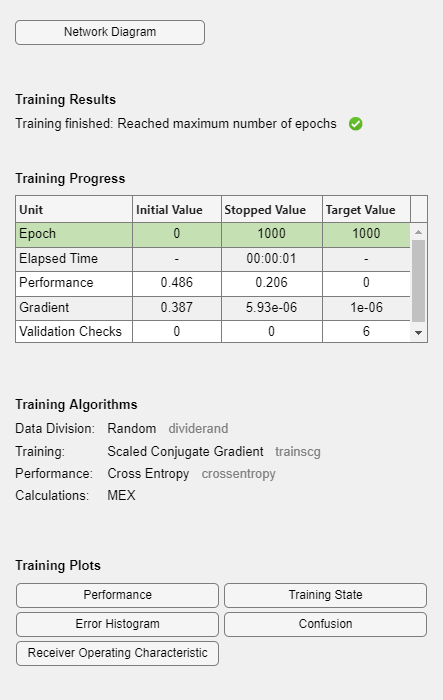


%help patternnet
net = patternnet(2); % two layers of neurons
net.divideParam.trainRatio = 100/100;
net.divideParam.valRatio = 0/100;
net.divideParam.testRatio = 0/100;
net = train(net, inputTrain, labelsTrain);

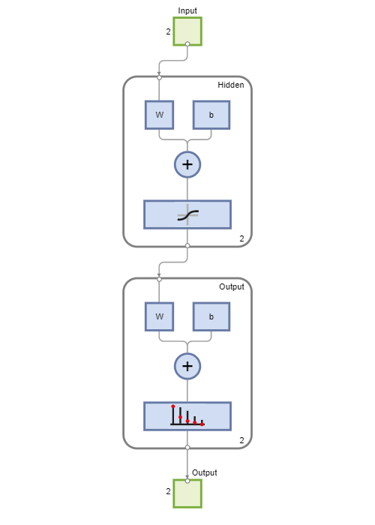

view(net);

scoreTrain = net(inputTrain); % ouput prediction

## Using patternnet function, please look up the usage of this function via "help patternnet"

%Part B:
disp("9.3b)")

9.3b)


datetime()

ans = datetime
   30-Nov-2023 18:46:02


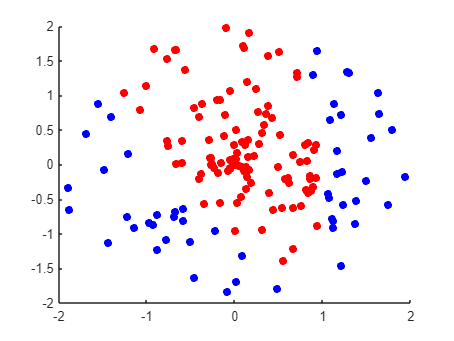


%scoreTrain = net(inputTrain); % ouput prediction
perfTrain = perform(net,labelsTrain,scoreTrain);
predictTrain = vec2ind(scoreTrain);
XpredictTrain = [inputTrain; predictTrain];
XpredictTrain_1 = XpredictTrain(:,XpredictTrain(3,:)==1);
XpredictTrain_2 = XpredictTrain(:,XpredictTrain(3,:)==2);
%Xy_1 = Xy(Xy(:,4)==1,:);
figure
scatter(XpredictTrain_1(1,:), XpredictTrain_1(2,:),'red','filled')
hold on
scatter(XpredictTrain_2(1,:), XpredictTrain_2(2,:),' blue','filled')
hold off


XpredictTrainLabels = [XpredictTrain; vec2ind(labelsTrain)];
CCRTrain = CCRlabels(XpredictTrainLabels);
disp('Training CCR')

Training CCR


disp(CCRTrain)

    0.8187





%Part C:
disp("9.3c)")

9.3c)


datetime()

ans = datetime
   30-Nov-2023 18:46:02


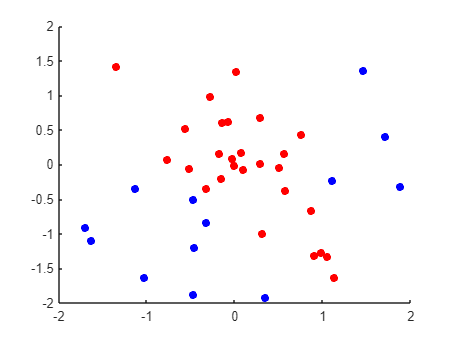


scoreTest = net(inputTest); % ouput prediction
perfTest = perform(net,labelsTest,scoreTest);
predictTest = vec2ind(scoreTest);
XpredictTest = [inputTest; predictTest];
XpredictTest_1 = XpredictTest(:,XpredictTest(3,:)==1);
XpredictTest_2 = XpredictTest(:,XpredictTest(3,:)==2);
%Xy_1 = Xy(Xy(:,4)==1,:);
figure
scatter(XpredictTest_1(1,:), XpredictTest_1(2,:),'red','filled')
hold on
scatter(XpredictTest_2(1,:), XpredictTest_2(2,:),'blue','filled')
xlim([-2,2])
ylim([-2,2])
hold off


XpredictTestLabels = [XpredictTest; vec2ind(labelsTest)];
CCRTest = CCRlabels(XpredictTestLabels);
disp('Test CCR')

Test CCR


disp(CCRTest)

    0.7250





%Part D:

disp("9.3d)a)")

9.3d)a)


datetime()

ans = datetime
   30-Nov-2023 18:46:03


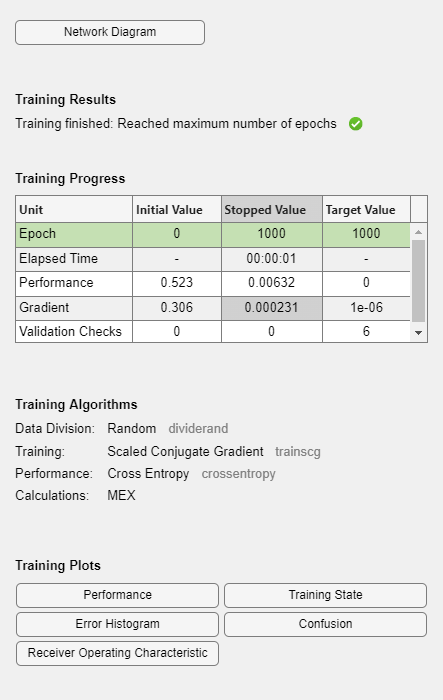


net10 = patternnet(10); % two layers of neurons
net10.divideParam.trainRatio = 100/100;
net10.divideParam.valRatio = 0/100;
net10.divideParam.testRatio = 0/100;
net10 = train(net10, inputTrain, labelsTrain);

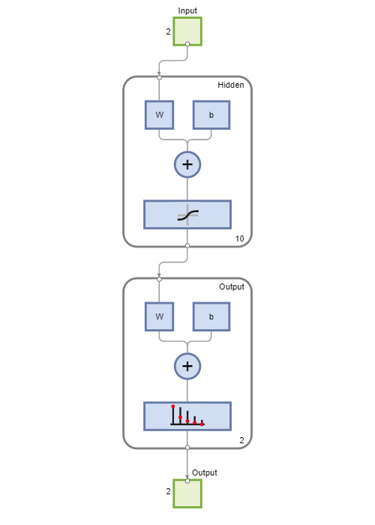

view(net10);



disp("9.3d)b)")

9.3d)b)


datetime()

ans = datetime
   30-Nov-2023 18:46:06


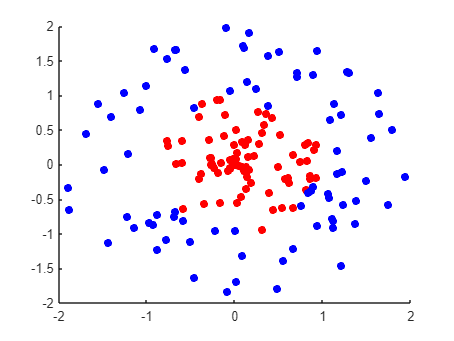

scoreTrain10 = net10(inputTrain); % ouput prediction
perfTrain10 = perform(net10,labelsTrain,scoreTrain10);
predictTrain10 = vec2ind(scoreTrain10);
XpredictTrain10 = [inputTrain; predictTrain10];
XpredictTrain10_1 = XpredictTrain10(:,XpredictTrain10(3,:)==1);
XpredictTrain10_2 = XpredictTrain10(:,XpredictTrain10(3,:)==2);
%Xy_1 = Xy(Xy(:,4)==1,:);
figure
scatter(XpredictTrain10_1(1,:), XpredictTrain10_1(2,:),'red','filled')
hold on
scatter(XpredictTrain10_2(1,:), XpredictTrain10_2(2,:),' blue','filled')
hold off

XpredictTrain10Labels = [XpredictTrain10; vec2ind(labelsTrain)];
CCRTrain10 = CCRlabels(XpredictTrain10Labels);
disp('10 Hidden Layer Training CCR')

10 Hidden Layer Training CCR


disp(CCRTrain10)

    0.9938




disp("9.3d)c)")

9.3d)c)


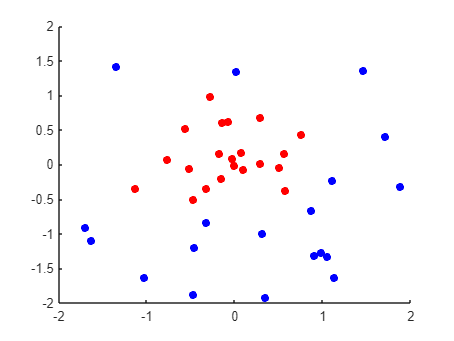

scoreTest10 = net10(inputTest); % ouput prediction
perfTest10 = perform(net10,labelsTest,scoreTest10);
predictTest10 = vec2ind(scoreTest10);
XpredictTest10 = [inputTest; predictTest10];
XpredictTest10_1 = XpredictTest10(:,XpredictTest10(3,:)==1);
XpredictTest10_2 = XpredictTest10(:,XpredictTest10(3,:)==2);
%Xy_1 = Xy(Xy(:,4)==1,:);
figure
scatter(XpredictTest10_1(1,:), XpredictTest10_1(2,:),'red','filled')
hold on
scatter(XpredictTest10_2(1,:), XpredictTest10_2(2,:),'blue','filled')
xlim([-2,2])
ylim([-2,2])
hold off

XpredictTest10Labels = [XpredictTest10; vec2ind(labelsTest)];
CCRTest = CCRlabels(XpredictTest10Labels);
disp('10 Hidden Layer Test CCR')

10 Hidden Layer Test CCR


disp(CCRTest)

    0.9250



datetime()

ans = datetime
   30-Nov-2023 18:46:07


%Part E:


function CCR = CCRlabels(data)
    predictlabels = data(3,:);
    correctlabels = data(4,:);
    CCR = 0;
    for i = 1:size(predictlabels,2)
        if predictlabels(1,i) == correctlabels(1,i)
            CCR = CCR + 1;
        end
    end
    CCR = CCR / size(predictlabels,2);
end